---------------------------------------------------------------------------

copyright@ Xiaoxing Hu Email:72744505@qq.com 

modifide history: 2022/5/28

version:1.0

exp2，探究故障库更新对故障辨识的影响

---------------------------------------------------------------------------

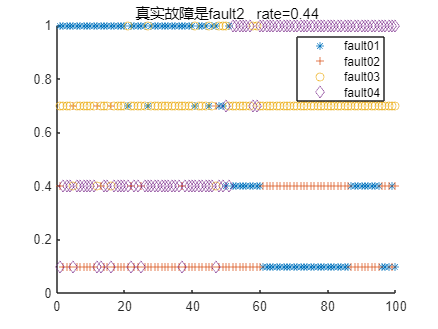

N1 = 100; %数据库大小
N2 = 100; %样本测试数量
score = [1 ,0.7, 0.4, 0.1];
weight = [1,1,0.1,0.08];%权重系数
rate = 0;%正确率
scorex = zeros(4,N2);%存放得分数据
timeflag = 1000;%时间戳
% test_type = 4;%测试故障为序号
%------------------------------------------------------------------------------
Data_fi1 = fault1_input(timeflag-N1+1:timeflag,:)';
Data_fo1 = fault1_output(timeflag-N1+1:timeflag,:)';
Data_fi2 = fault2_input(timeflag-N1+1:timeflag,:)';
Data_fo2 = fault2_output(timeflag-N1+1:timeflag,:)';
% in2 = zeros(1000,4);
% in2(901:1000,:) = Data_fi2';
% out2 = zeros(1000,4);
% out2(901:1000,:) = Data_fo2';
Data_fi3 = fault3_input(timeflag-N1+1:timeflag,:)';
Data_fo3 = fault3_output(timeflag-N1+1:timeflag,:)';
Data_fi4 = fault4_input(timeflag-N1+1:timeflag,:)';
% in4 = zeros(1000,4);
% in4(901:1000,:) = Data_fi4';
Data_fo4 = fault4_output(timeflag-N1+1:timeflag,:)';
% out4 = zeros(1000,4);
% out4(901:1000,:) = Data_fo4';
for j = timeflag+1:timeflag+N2 %1001:1100
    data_all = [fault1_input(j,:),fault1_output(j,:);fault2_input(j,:),fault2_output(j,:);fault3_input(j,:),fault3_output(j,:);fault4_input(j,:),fault4_output(j,:)];
    %data:4x8
    data_test = data_all(test_type,:)';
    [S1,Omega_fault1] = make_Omega(Data_fi1,Data_fo1);
    [S2,Omega_fault2] = make_Omega(Data_fi2,Data_fo2);
    [S3,Omega_fault3] = make_Omega(Data_fi3,Data_fo3);
    [S4,Omega_fault4] = make_Omega(Data_fi4,Data_fo4);
    Omega = [Omega_fault1,Omega_fault2,Omega_fault3,Omega_fault4];%4x32
    sum = zeros(1,4);%计算残差的大小
    vec = zeros(4,4);%行数表示残差的深度，列数表示Omega的种类
    for k = 1:4 %4个Omega
        vectemp = Omega(:,8*k-7:8*k) * data_test;
        vec(:,k) = vectemp;%4x4每一列代表一个Omega得到的残差
    end
    for k = 1:4
        for l = 1:2%计算残差的个数 s =2
           sum(k) = sum(k) + weight(l)*abs(vec(l,k));
        end
    end
    [sorted_sum, index] = sort(sum);
    scorex(1,j-timeflag) =  score(find(sorted_sum==sum(1)));%find：找到原来的数在排序后的索引
    scorex(2,j-timeflag) =  score(find(sorted_sum==sum(2)));
    scorex(3,j-timeflag) =  score(find(sorted_sum==sum(3)));
    scorex(4,j-timeflag) =  score(find(sorted_sum==sum(4)));
%     index(1)
    if index(1) == 1
        Temp_in = zeros(4,N1);
        Temp_out = zeros(4,N1);
        Temp_in(:,1:N1-1) = Data_fi1(:,2:N1);
        Temp_in(:,N1) = data_test(1:4)';
        Temp_out(:,1:N1-1) = Data_fo1(:,2:N1);
        Temp_out(:,N1) = data_test(5:8)';
        Data_fi1 = Temp_in;
        Data_fo1 = Temp_out;
    elseif index(1) == 2
        Temp_in = zeros(4,N1);
        Temp_out = zeros(4,N1);
        Temp_in(:,1:N1-1) = Data_fi2(:,2:N1);
        Temp_in(:,N1) = data_test(1:4)';
        Temp_out(:,1:N1-1) = Data_fo2(:,2:N1);
        Temp_out(:,N1) = data_test(5:8)';
        Data_fi2 = Temp_in;
        Data_fo2 = Temp_out;
    elseif index(1) == 3
        Temp_in = zeros(4,N1);
        Temp_out = zeros(4,N1);
        Temp_in(:,1:N1-1) = Data_fi3(:,2:N1);
        Temp_in(:,N1) = data_test(1:4)';
        Temp_out(:,1:N1-1) = Data_fo3(:,2:N1);
        Temp_out(:,N1) = data_test(5:8)';
        Data_fi3 = Temp_in;
        Data_fo3 = Temp_out;
    elseif index(1) == 4
        Temp_in = zeros(4,N1);
        Temp_out = zeros(4,N1);
        Temp_in(:,1:N1-1) = Data_fi4(:,2:N1);
        Temp_in(:,N1) = data_test(1:4)';
        Temp_out(:,1:N1-1) = Data_fo4(:,2:N1);
        Temp_out(:,N1) = data_test(5:8)';
        Data_fi4 = Temp_in;
        Data_fo4 = Temp_out;
    end
    if(scorex(test_type,j-timeflag)==1)
       rate=rate+1;
    end
end
myplot1(scorex,rate,test_type)

temp_i = zeros(1100,4);
temp_i(1001:1100,:) = Data_fi4';
temp_o = zeros(1100,4);
temp_o(1001:1100,:) = Data_fo4';